## **Simulating Chirp Signal**

**Loading in Data**

% Define file path
folder_path = '/Users/khavishgovind/Library/CloudStorage/OneDrive-UniversityofCapeTown/Masters/CSV_Files';
file_name = 'radar_data_Mipur.mat';
file_path = fullfile(folder_path, file_name);

% Load the radar data from the .mat file
data = load(file_path);
radar_data = data.radar_data;

## *****Matlab is 1 indexing so add 1 to all rows**

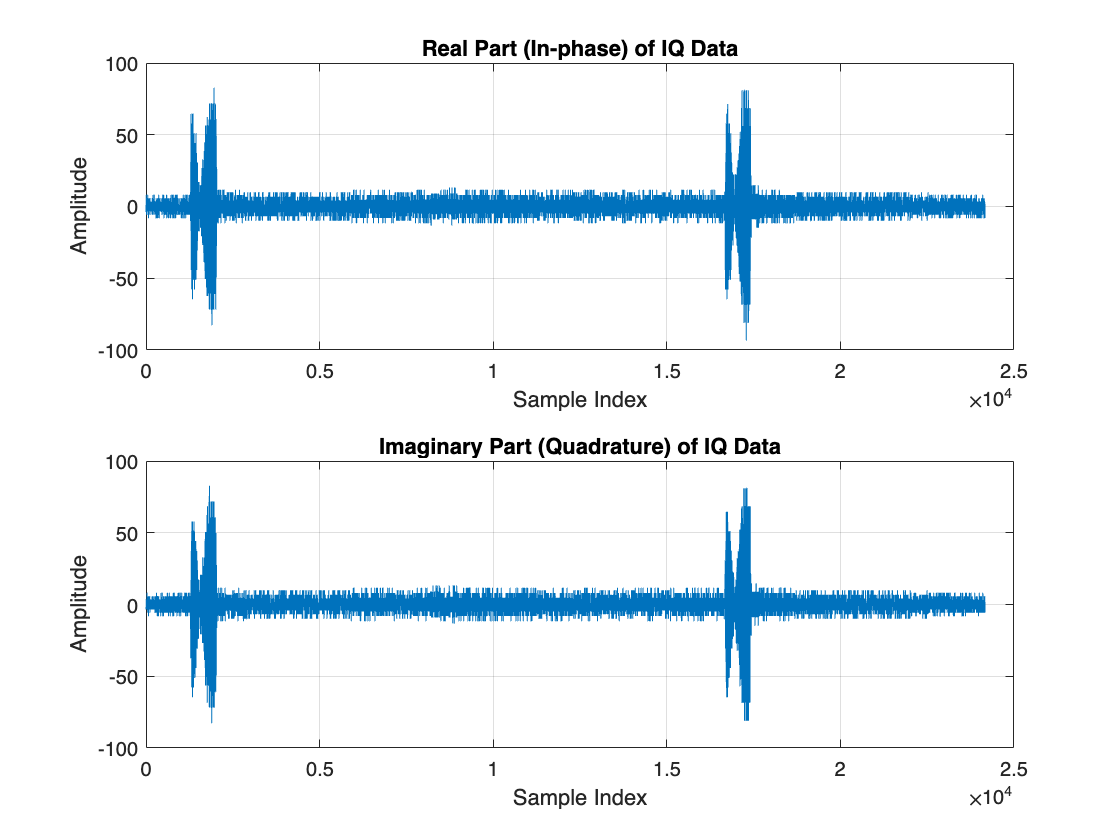

% Extract row signal (IQ data)
row_idx = 1201;  % Row to analyze
iq_data = radar_data(row_idx, :);  % Assuming radar_data is a complex matrix (I + jQ)

% Plot the IQ data (Real part for I and Imaginary part for Q)
figure;
subplot(2, 1, 1);  % Two subplots, first for real (I)
plot(real(iq_data));  % Plot the real part (I)
title('Real Part (In-phase) of IQ Data');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);  % Second subplot for imaginary (Q)
plot(imag(iq_data));  % Plot the imaginary part (Q)
title('Imaginary Part (Quadrature) of IQ Data');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

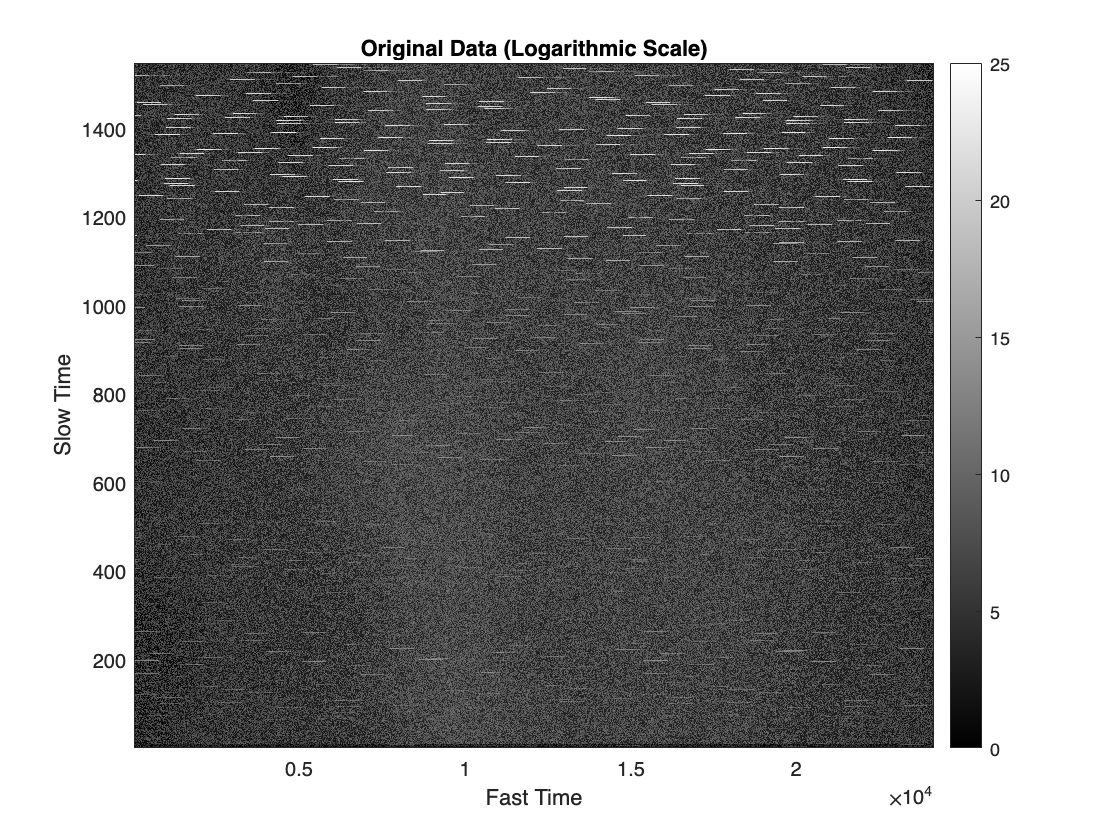

% Check if the data is complex and take the magnitude
radar_data_magnitude = abs(radar_data); 

% Apply logarithm to the magnitude (dB scale)
radar_data_log = 10 * log10(radar_data_magnitude + eps);  % Avoid log10(0) issues

% Create a new figure window
figure;

% Plot
imagesc(radar_data_log);  
colormap('gray');  
colorbar;

% Set the color axis limits
clim([0, 25]);  % Replace min_val and max_val with desired values

% Customize plot
xlabel('Fast Time');
ylabel('Slow Time');
title('Original Data (Logarithmic Scale)');
axis tight;
axis xy;  % Prevent flipping
set(gca, 'YDir', 'normal');  % Match y-axis orientation

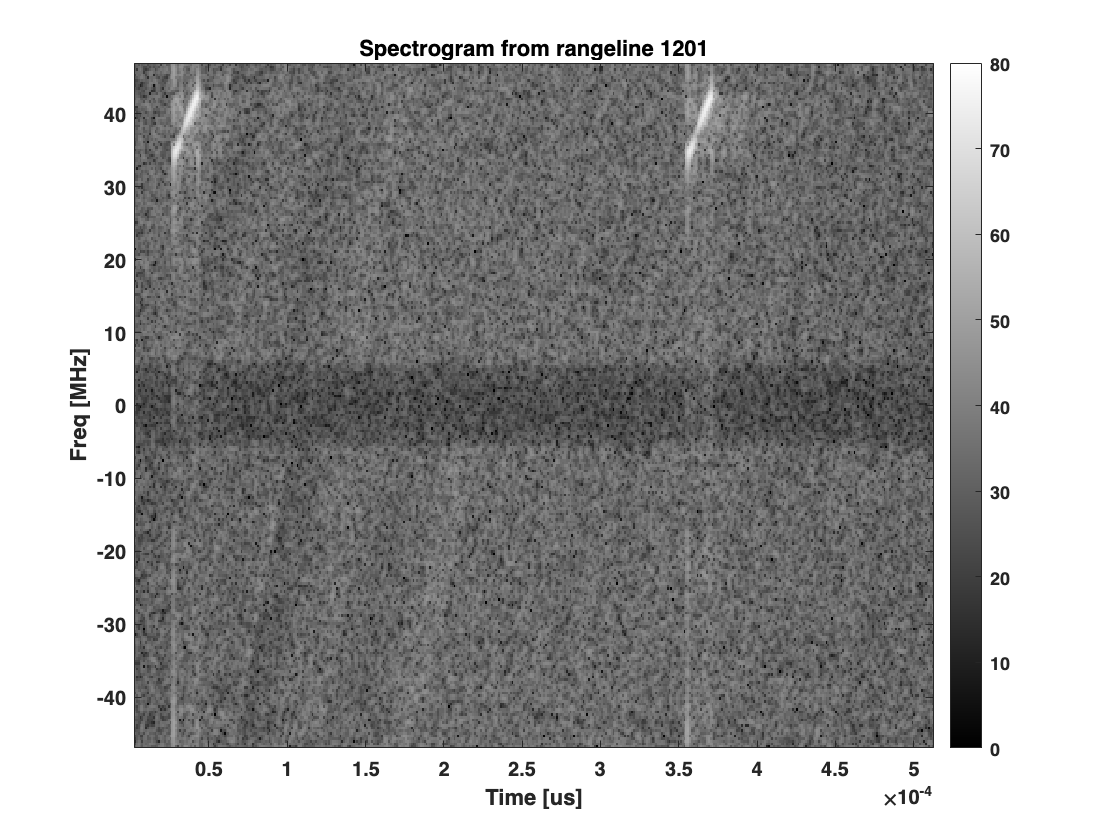

% Define spectrogram parameters
nfft = 256;  % Number of FFT points
window = hanning(nfft);  % Use Hanning window like in Python
noverlap = 200;  % Overlap (matches your Python script)
row_idx = 1201;  % Row to analyze
fs_MHz = fs / 1e6;  % Convert sampling rate to MHz (for display only)

% Extract row signal
row_signal = radar_data(row_idx, :);

% Compute spectrogram
figure(11);
clf;  % Clear figure before plotting
[S, F, T,P] = spectrogram(row_signal, window, noverlap, nfft, fs);  % Compute spectrogram in Hz

% Convert to dB scale (to match Python)
S_dB = 10 * log10(abs(S).^2);  % Power spectrogram in dB

% Convert frequency axis to MHz (same as Python)
F = F / 1e6;  % Convert frequencies to MHz

% Create a symmetric frequency axis (both positive and negative frequencies)
F_centered = [-flipud(F(2:end)); F];  % Center frequencies around zero

% Save the spectrogram data (dB scale and time vector) to a .mat file
save('matlab_spectrogram.mat', 'S_dB', 'T', 'F_centered');

% Plot the spectrogram with the frequency axis centered around 0
imagesc(T, F_centered, S_dB);  % Plot in dB scale
colormap('gray');  % Match Python's 'Greys' colormap
colorbar;

% Set color axis limits (dB scale)
clim([0, 80]);  % Adjusting color axis limits for a similar display

% Customize plot for similar style to Python
xlabel('Time [us]', 'FontWeight', 'bold');
ylabel('Freq [MHz]', 'FontWeight', 'bold');
title(['Spectrogram from rangeline ', num2str(row_idx)], 'FontWeight', 'bold');
set(gca, 'FontWeight', 'bold');

% Adjust layout
set(gca, 'YDir', 'normal');  % Ensure frequency axis is in the correct order (low to high)

**Creating simulated Chirp Signal**

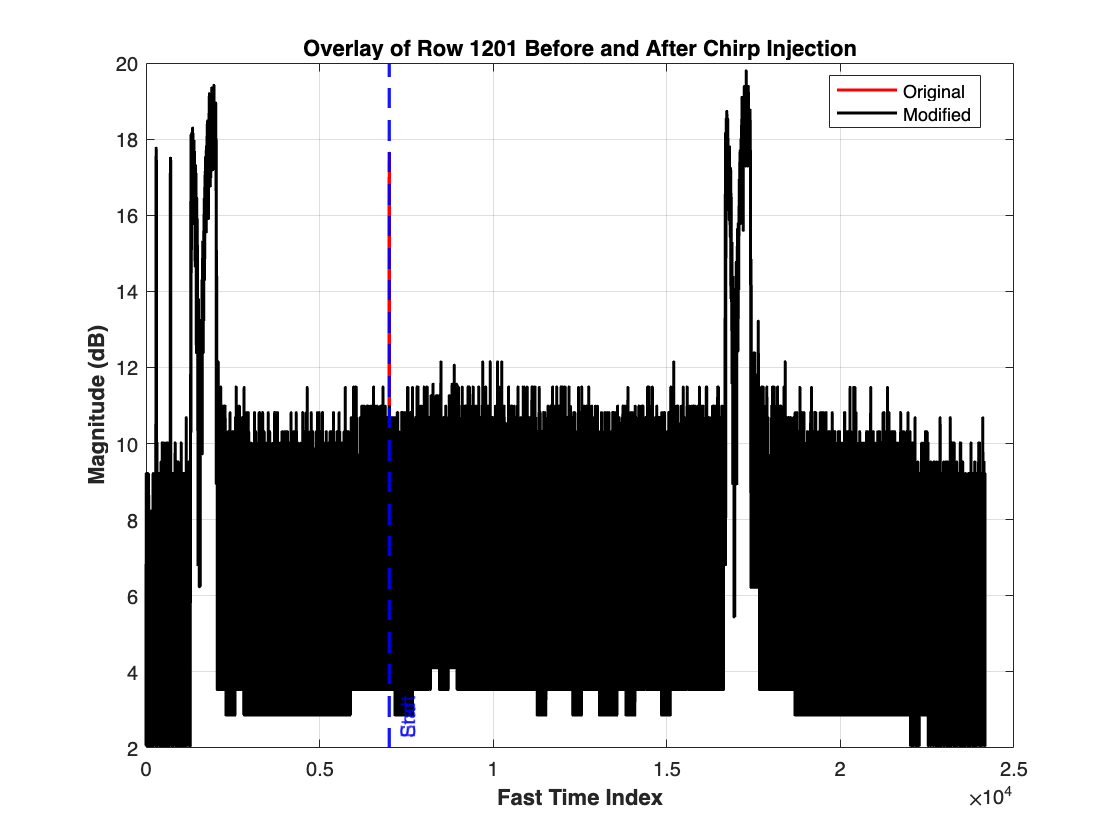

% Define chirp parameters
fs = 46918402.800000004;  % Sampling frequency (Hz)
bw = 4.765150284375e6;  % Bandwidth (Hz)
fc = -4.4997175099137925e6;  % Center frequency (Hz)
chirp_rate = 0.3403678774553572e6 / 1e-6;  % Chirp rate (Hz/s)

% Define start and end time indices
start_idx = 7000;
end_idx = 7014;

% Create time vector based on start and end indices
T = (end_idx - start_idx + 1) / fs;  % Compute duration from indices
t = linspace(0, T, end_idx - start_idx + 1);  

% Generate linear chirp signal
chirp_signal = 50*exp(1j * (2 * pi * (fc * t + 0.5 * chirp_rate * t.^2)));

% Select a row to inject the chirp into
row_idx = 1201;  % Change this to select the row

% Get the number of columns in the radar data
num_cols = size(radar_data, 2);

% Store a copy of the original radar data for comparison
radar_data_original = radar_data(row_idx, :);

% Create a zero-padded signal matching the radar data width
chirp_signal_padded = zeros(1, num_cols);
chirp_signal_padded(start_idx:end_idx) = chirp_signal;  % Inject chirp within indices

% Inject chirp into the selected row
radar_data(row_idx, :) = radar_data(row_idx, :) + chirp_signal_padded;

% Extract modified row
radar_data_modified = radar_data(row_idx, :);

% Plot the original and modified row signals
figure;
plot(10 * log10(abs(radar_data_modified) + eps), 'r', 'LineWidth', 1.5);
hold on;
plot(10 * log10(abs(radar_data_original) + eps), 'k', 'LineWidth', 1.5); 
hold off;

% Mark the chirp insertion region
xline(start_idx, '--b', 'Start', 'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom');
xline(end_idx, '--b', 'End', 'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom');

% Customize the plot
xlabel('Fast Time Index', 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontWeight', 'bold');
title(['Overlay of Row ', num2str(row_idx), ' Before and After Chirp Injection'], 'FontWeight', 'bold');
legend({'Original', 'Modified'}, 'Location', 'Best');
grid on;

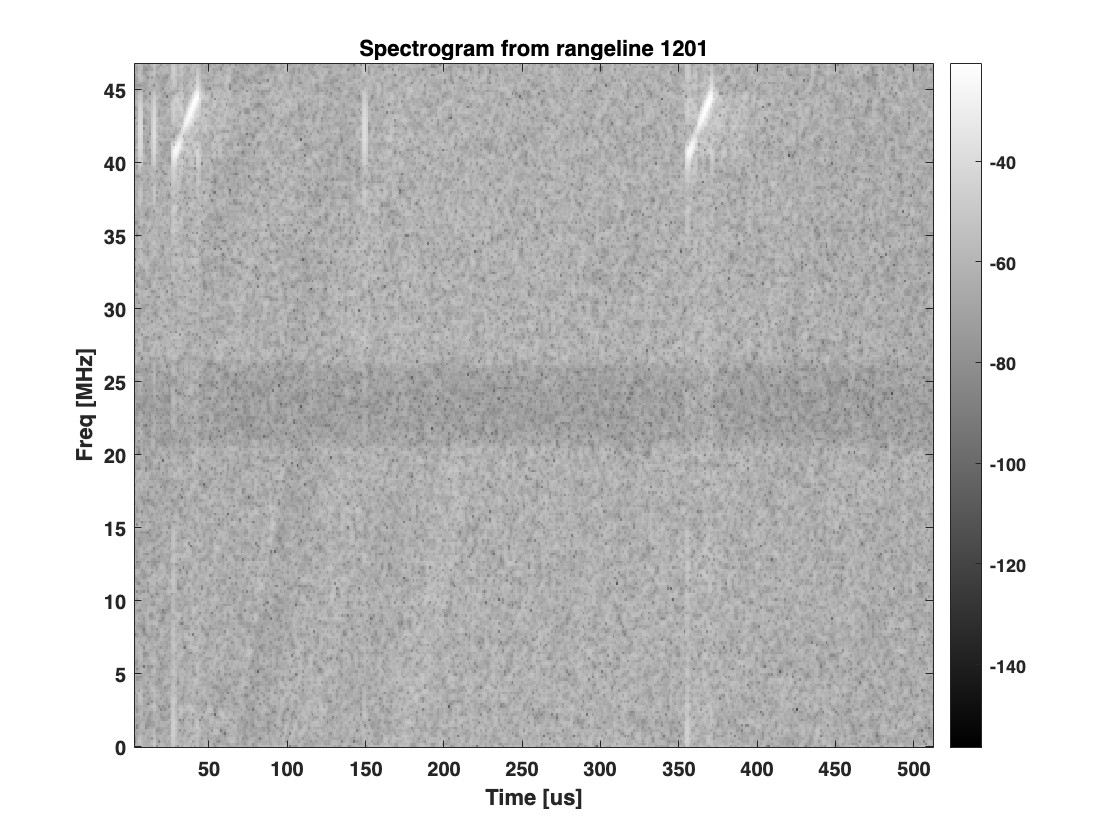

% Define spectrogram parameters
nfft = 256;  % Number of FFT points
window = hanning(nfft);  % Use Hanning window like in Python
noverlap = 200;  % Overlap (matches your Python script)
row_idx = 1201;  % Row to analyze

% Extract row signal
row_signal = radar_data(row_idx, :); 

% Compute spectrogram
figure(11);
clf;  % Clear figure before plotting
spectrogram(row_signal, window, noverlap, nfft, fs, 'yaxis');

% Customize plot for similar style to Python
colormap('gray');  % Match Python's 'Greys' colormap
colorbar;
xlabel('Time [us]', 'FontWeight', 'bold');
ylabel('Freq [MHz]', 'FontWeight', 'bold');
title(['Spectrogram from rangeline ', num2str(row_idx)], 'FontWeight', 'bold');
set(gca, 'FontWeight', 'bold');

% Adjust layout
set(gca, 'YDir', 'normal'); % Keep frequency axis orientation consistent